Read images

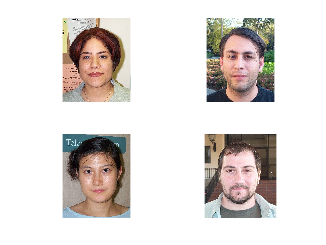

folder = "DB0"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

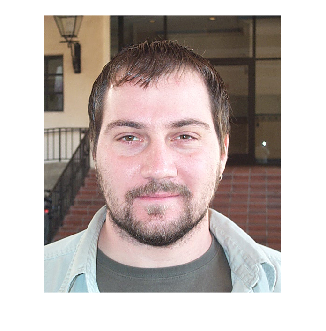

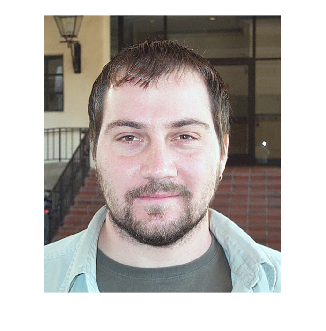

ans = ans(:,:,1) =

    0.5626    0.5810    0.5847    0.5884    0.5921    0.5884    0.5884    0.5847    0.5810    0.5810    0.5774    0.5847    0.5774    0.5663    0.5774    0.5921    0.5810    0.5957    0.5626    0.4450    0.3677    0.2611    0.2537    0.2758    0.3015    0.3494    0.3236    0.3273    0.3236    0.3420    0.3199    0.3861    0.3604    0.3383    0.3604    0.3383    0.3530    0.3641    0.3714    0.4008    0.4155    0.4303    0.3972    0.3861    0.3641    0.3641    0.3714    0.3677    0.3751    0.3824    0.4045    0.4119    0.4045    0.3972    0.3788    0.3714    0.3972    0.3824    0.3714    0.3824    0.3530    0.3751    0.3935    0.3530    0.3714    0.3677    0.2868    0.2758    0.2243    0.2832    0.3236    0.3714    0.3972    0.4119    0.4045    0.3972    0.4082    0.3714    0.3310    0.3052    0.2684    0.2942    0.3420    0.4082    0.5295    0.5810    0.6399    0.6435    0.6362    0.6435    0.6435    0.6509    0.6435    0.6583    0.6619    0.6509    0.6399    0.6362

%The following requires image processing toolbox.
currentImage = Im{4};
lighting_compensation(currentImage, 0.05)

Mouth map

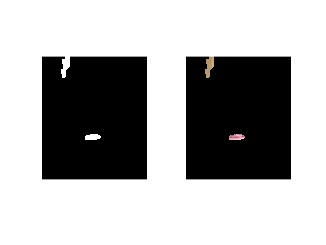

MouthMap = mouth_detection(currentImage);
figure;
subplot(1,2,1);
imshow(MouthMap);
subplot(1,2,2);
imshow(currentImage.*MouthMap);

Form an eye-mouth triangle.

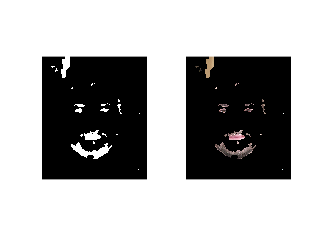

Triangle = EyeMap + MouthMap;
figure;
subplot(1,2,1);
imshow(Triangle);
subplot(1,2,2);
imshow(Triangle.*currentImage);

To test the eye detection implementation.

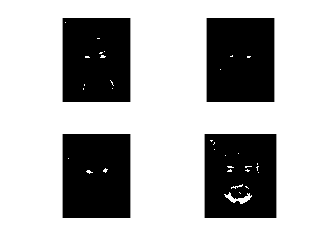

figure;
for i = 1:length(Im)
    subplot(length(Im)/2, length(Im)/2, i); %%define location to plot the image in our subplot.
    [hybridImage] = eye_detection(Im{i});
    imshow(hybridImage);
end 